% Setup
format compact
clearvars
clc
%hold off;

% Variables
TFG_Preload()

inputGain = 2; % És l'amplitud de totes les consignes (valor constant, amplitud de graó i rampa, valor de pic del sinus)
inputType = 2; % 1 - Constant | 2 - Graó | 3 - Rampa | 4 - Sinus
inputOffset = 0; % Per exemple, per a que el motor no pari mai (evitar fregament estàtic en real. vel.)
loopType = 3; % 1 - Llaç obert | 2 - Llaç tancat amb Vtac | 3 - Llaç tancat amb Vpot

% Posar les Kx a -1 per a fer servir assignació de pòls
Kp = 2; % 2
Ki = 9; % 9
Kd = 0.05; % 0.05

% Parametres
OL2V = load('./Data/VelObert2v.mat');
OL2V = OL2V.simout;
VF2V = mean(OL2V(2500:3000,2));
Km2V = VF2V/(2*Ktac)

Km2V = single
45.1023

Val632V = VF2V*0.63

Val632V = single
0.7604

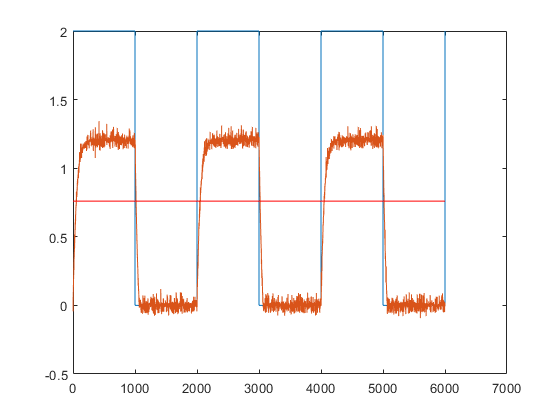

figure();
plot(OL2V(:,1:2),'DisplayName','OL2V');
hold on;
plot([0 length(OL2V)-1], [Val632V Val632V], 'r-');

tau2V = (2051-2000)*30/6000 % 30/6000 segons/mostra

tau2V = 0.2550


OL3V = load('./Data/VelObert3v.mat');
OL3V = OL3V.simout;
VF3V = mean(OL3V(2500:3000,2));
Km3V = VF3V/(3*Ktac)

Km3V = single
49.0555

Val633V = VF3V*0.63

Val633V = single
1.2405

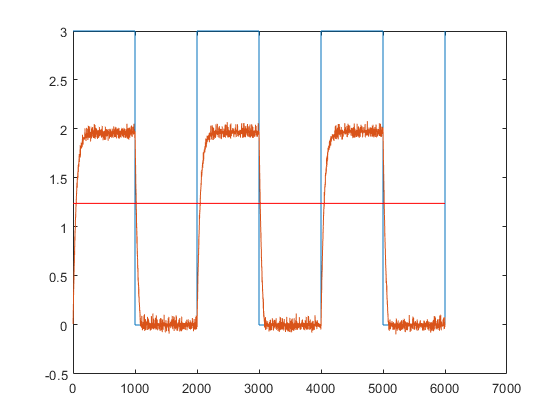

figure();
plot(OL3V(:,1:2),'DisplayName','OL3V');
hold on;
plot([0 length(OL3V)-1], [Val633V Val633V], 'r-');

tau3V = (2051-2000)*30/6000 % 30/6000 segons/mostra

tau3V = 0.2550

## Teoria

#### Càlcul del PID en pos per assignació de pols

s1 = -5;
s2 = -0.6+9i;
s3 = -0.6-9i;

Kdn = ((-s2-s3-s1)*9*tau-9)/(K*Kpot)

Kdn = 0.0508

Kpn = (s1*s2+s1*s3+s2*s3)*9*tau/(K*Kpot)

Kpn = 1.9471

Kin = -s1*s2*s3*9*tau/(K*Kpot)

Kin = 9.0670


if (Kp == -1)&&(Ki == -1)&&(Kd == -1)
    Kp = Kpn;
    Ki = Kin;
    Kd = Kdn;
end

% Pos - PIDn
if loopType == 3
    G = tf(inputGain.*[K*Kpot*Kdn K*Kpot*Kpn K*Kpot*Kin], [9*tau 9+K*Kpot*Kdn K*Kpot*Kpn K*Kpot*Kin]);
elseif loopType == 2
    G = tf(inputGain*(K*Ktac).*[Kdn Kpn Kin], [tau+Kdn*K*Ktac 1+Kpn*K*Ktac Kin*K*Ktac]);
end
pole(G)

ans =   -0.6000 + 9.0000i
  -0.6000 - 9.0000i
  -5.0000 + 0.0000i


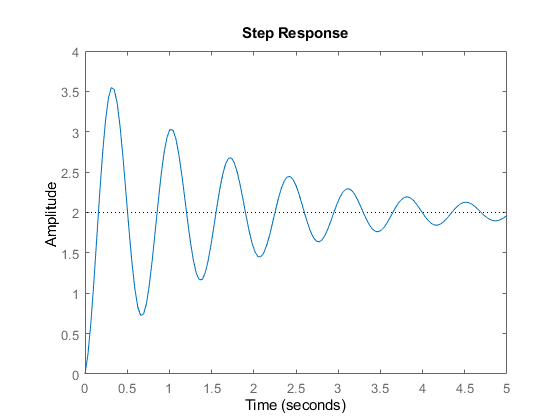

figure()
step(G, 5)

#### FT Actual

if loopType == 3
    FT = tf(inputGain.*[K*Kpot*Kd K*Kpot*Kp K*Kpot*Ki], [9*tau 9+K*Kpot*Kd K*Kpot*Kp K*Kpot*Ki]);
elseif loopType == 2
    FT = tf(inputGain*(K*Ktac).*[Kd Kp Ki], [tau+Kd*K*Ktac 1+Kp*K*Ktac Ki*K*Ktac]);
end
pole(FT)

ans =   -0.6598 + 9.1051i
  -0.6598 - 9.1051i
  -4.8453 + 0.0000i


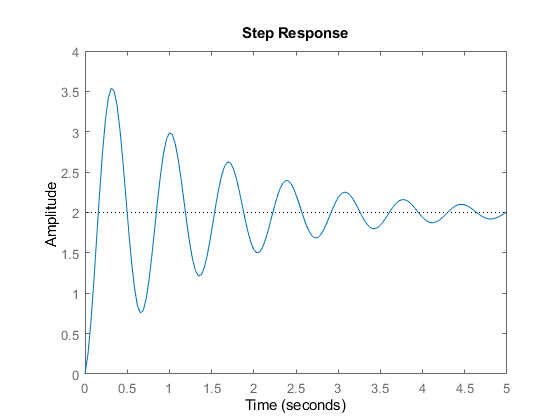

figure()
step(FT, 5)

## Simulació

#### Tractament de dades

Tsim = 30;
Tmin = 10;
Tmax = 20;

%out = sim('PlantaTFG.slx', Tsim);
out = sim('PlantaTFG2020a.slx', Tsim);
IndexObj = (Tmin < out.tout) & (out.tout < Tmax);
Consigna = out.Consigna.Data(IndexObj);
Posicio = out.Posicio.Data(IndexObj);
Velocitat = out.Velocitat.Data(IndexObj);
u = out.u.Data(IndexObj);
tout = out.tout(IndexObj);
IndexMid = tout == 15;

#### Graficació

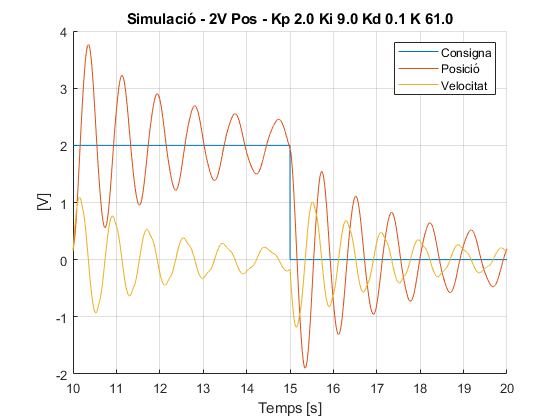

figure();
hold on;
grid on;
plot(tout, Consigna);
%if (loopType == 3); plot(tout, Posicio); end
plot(tout, Posicio);
plot(tout, Velocitat);
ylabel('[V]');
xlabel('Temps [s]');
legend('Consigna', 'Posició', 'Velocitat');
% titleString -> 'Simulació - Entrada Real. - Controlador'
titleString = sprintf('Simulació - %.0fV ', inputGain);
if (loopType == 1); titleString = [titleString, 'Obert']; end
if (loopType == 2); titleString = [titleString, 'Vel']; end
if (loopType == 3); titleString = [titleString, 'Pos']; end
titleString = [titleString, ' - '];
if (Kp ~= 0); titleString = [titleString, sprintf('Kp %.1f ', Kp)]; end
if (Ki ~= 0); titleString = [titleString, sprintf('Ki %.1f ', Ki)]; end
if (Kd ~= 0); titleString = [titleString, sprintf('Kd %.1f', Kd)]; end
titleString = [titleString, sprintf(' K %.1f', K)];
title(titleString)
hold off;

%exportgraphics(gcf, [titleString, '.png']);

#### Gràfic 3D

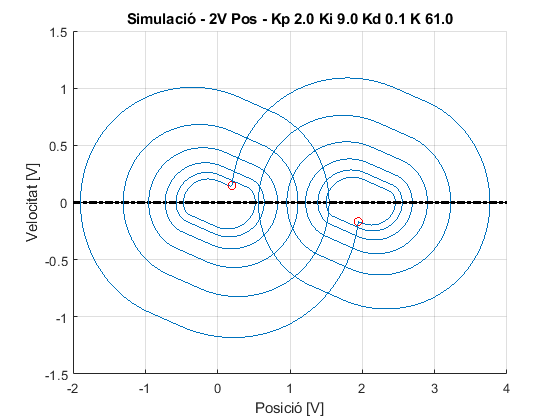

if sum([abs(Posicio)>5; abs(Velocitat)>5; abs(u)>5])>0
    fprintf("------  Existeixen valors anòmals >5V  ------")
    if corrAnom
        Posicio(abs(Posicio)>5) = 0;
        Velocitat(abs(Velocitat)>5) = 0;
        u(abs(u)>5) = 0;
    end
end

figure();
hold on;
grid on;
plot3(Posicio, Velocitat, u);
plot3(Posicio(1), Velocitat(1), u(1),'ro');
plot3(Posicio(IndexMid), Velocitat(IndexMid), u(IndexMid),'ro');
extremFill = xlim;
fill3([extremFill(2), extremFill(2), extremFill(1), extremFill(1)], [0, 0, 0, 0], [Vdi, Vds, Vds, Vdi], 'r');
alpha(0.3);
plot3(extremFill, [0 0], [0 0], 'k-.', 'LineWidth', 2);
xlabel('Posició [V]')
ylabel('Velocitat [V]')
zlabel('u [V]')
title(titleString);
hold off;